# ECMOR-2022 Paper

gen_q_pos = @(k) (-4)^(k) * (rand()-0.5)^(2*k+1)+0.5;
calc_g = @(u) [1 + 0.5 * u.^2, u];

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

ng_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

newton_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

## Theory

### Train / Test samples

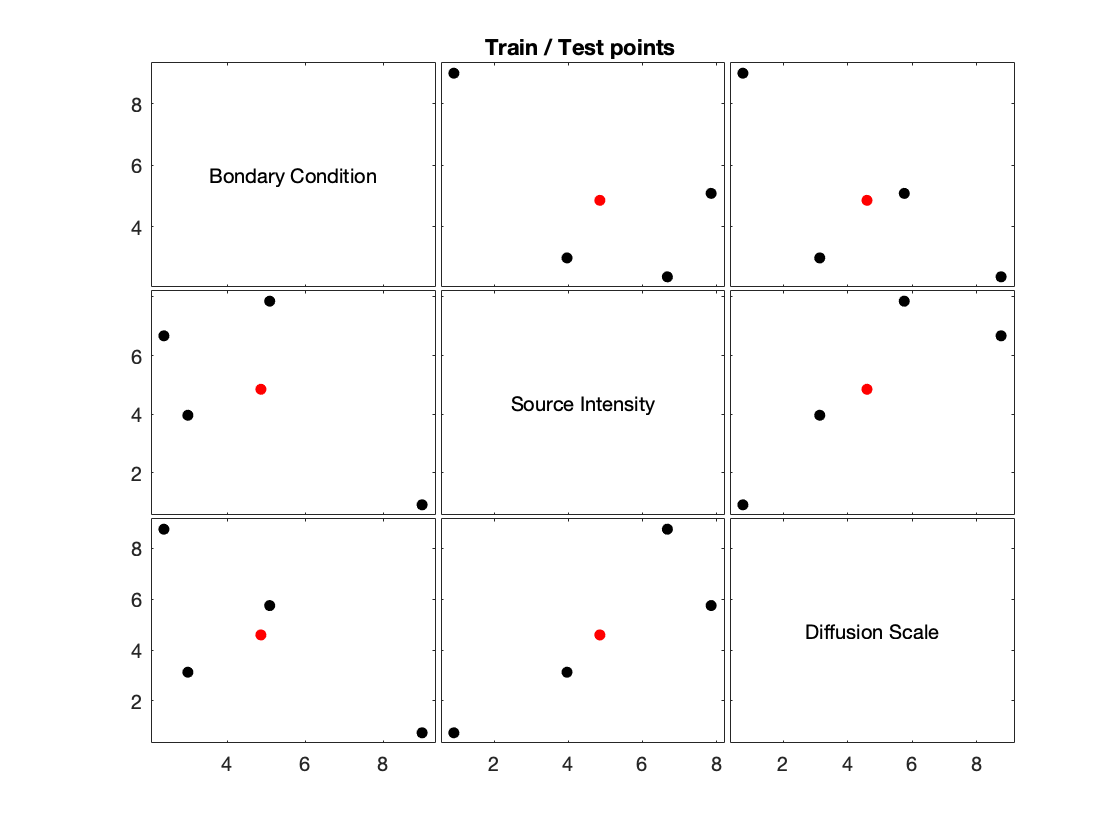

param_names = {'Bondary Condition';'Source Intensity';'Diffusion Scale'};
num_params = length(param_names);
num_train_points = num_params + 1;

train_points = lhsdesign(num_train_points, num_params, 'Smooth','on');

param_scales = [10, 10,  10];
param_biases = [ 0,  0, 0.1];

train_points = train_points .* param_scales + param_biases;

test_point = mean(train_points,1);

all_points = [train_points; test_point];

point_names = split(num2str(1:num_train_points));
point_names{end+1} = 'test point';
gplotmatrix(figure(),all_points,[],point_names,'kkkkr','.',[],'off','variable',param_names);
title('Train / Test points');

### FOM

Stable parameters

Nx = 1000;

param_gen_h = 0.1;
param_gen_clx = 0.1;
initial_condition = genField(Nx, 0, 2, param_gen_h, param_gen_clx);

Variable parameters

q_pos = gen_q_pos(1);
kappa = genField(Nx + 1, 1e-3, 1e-4, param_gen_h, param_gen_clx);

Problem

test_params = gen_params_from(Nx, test_point, q_pos, kappa);
FOM_test = genProblem('FOM',Nx,test_params,initial_condition);
Nt = 100;
FOM_test = solveDif(1, Nt, FOM_test, newton_solver);

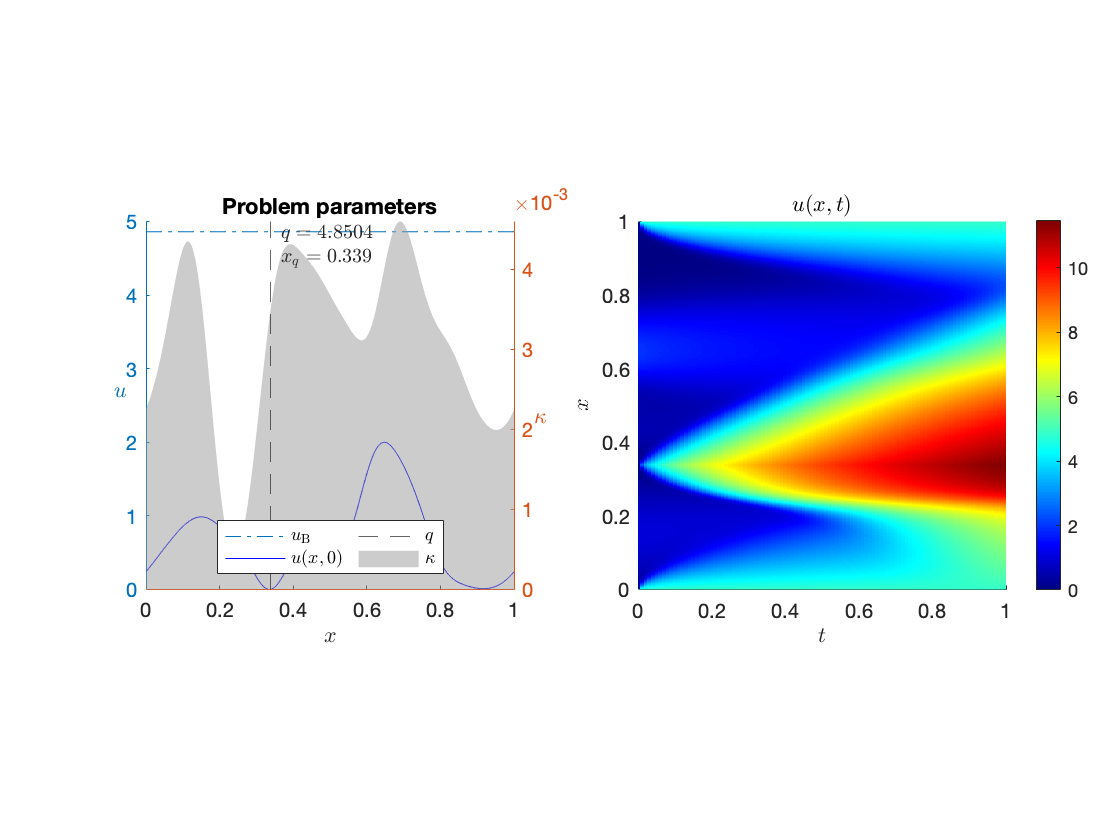

plotSol(figure(),FOM_test);

### ROM

Data

[X_test,W_test,J_test,~] = collectSolData(FOM_test);

#### POD

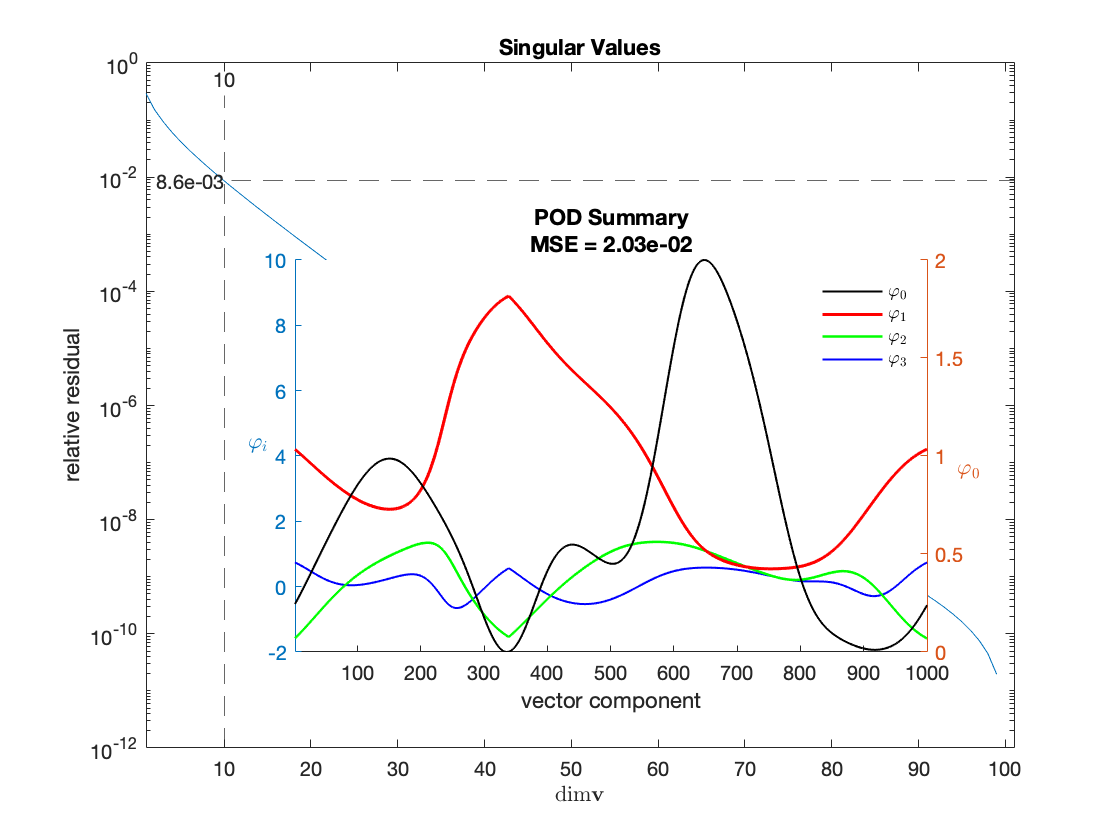

POD_test = PCA(X_test, 1e-2,'init',initial_condition).plotSummary(figure(), 'layout','built-in');

#### ROM-I

ROM_I_test = genProblem('ROM-I', Nx, test_params,initial_condition, POD_test.genEncoder());
ng_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD_test.genEncoder().decjac);
ROM_I_test = solveDif(1,Nt,ROM_I_test,ng_solver);
ROM_I_test.X = POD_test.decode(ROM_I_test.X);

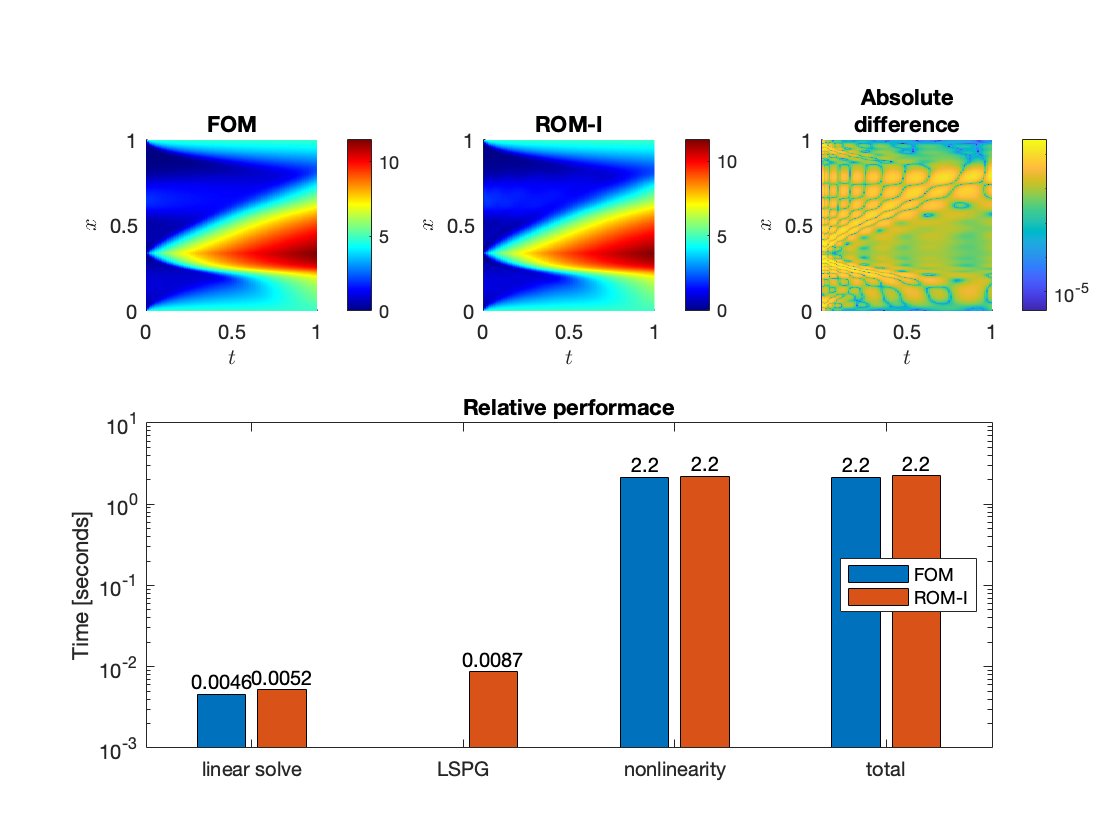

plotComp(figure(),FOM_test,ROM_I_test);

#### Gappy

PODs

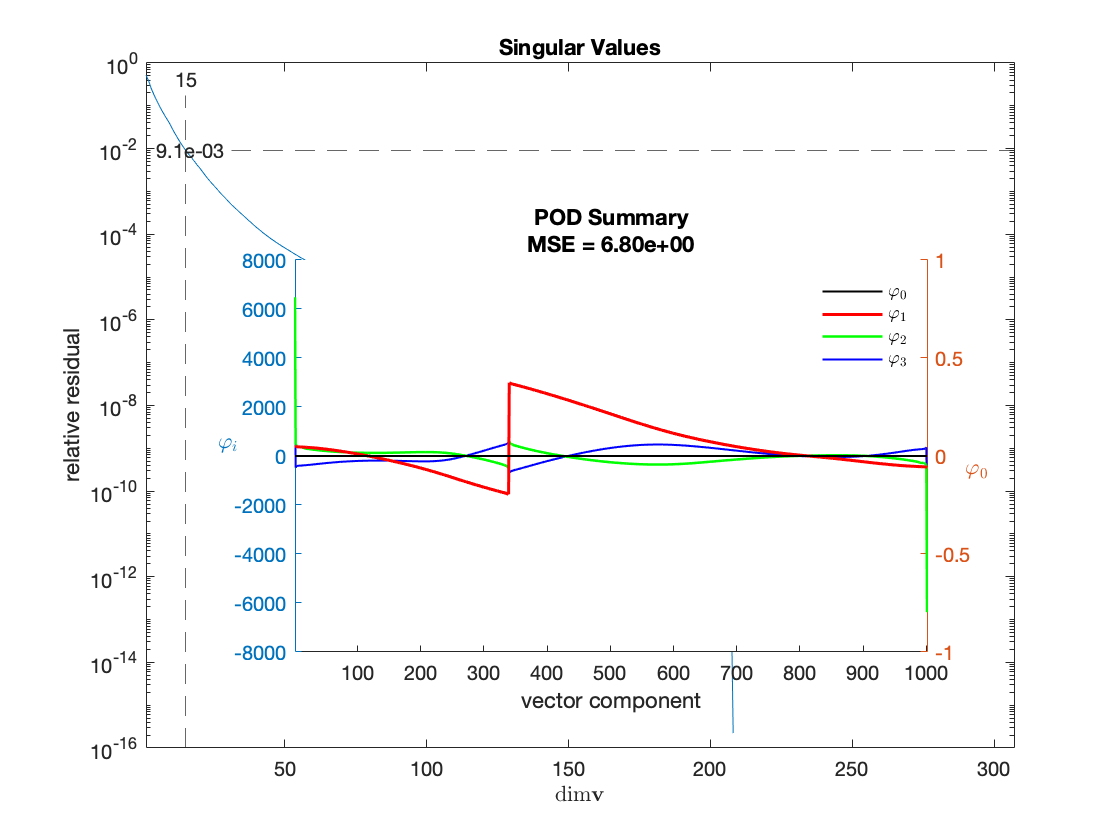

Gappy_W_test = PCA(W_test, 1e-2,'init',zeros(Nx+1,1)).plotSummary(figure(), 'layout','built-in');

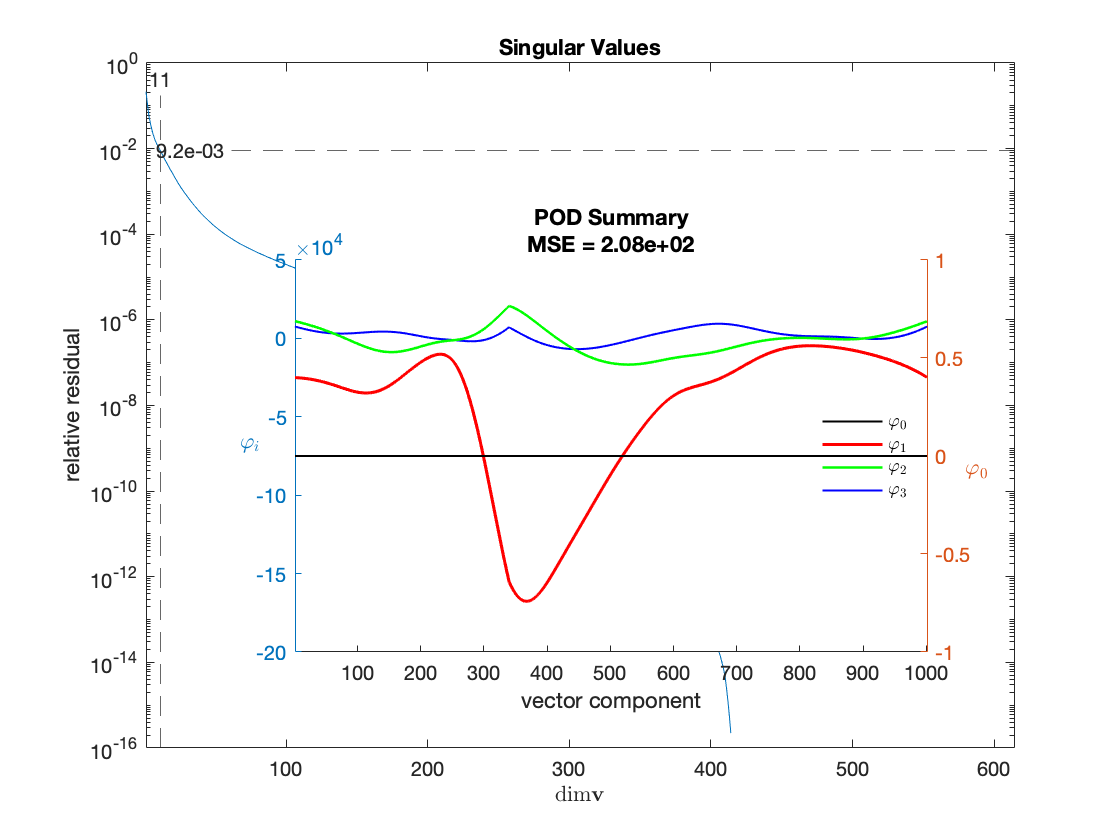

Gappy_J_test = PCA(J_test, 1e-2,'init',zeros(Nx+1,1)).plotSummary(figure(), 'layout','built-in');

Greedy mask

Oblique projections

#### ROM-II

text

## Method

Text

## Functions

function [out] = gen_params_from(Nx, point, q_pos, kappa)
bc_val = point(1);
boundary_condition = repmat(bc_val,1,2);
BC = genBC(1,boundary_condition);

kappa_scale = point(3);
medium = kappa * kappa_scale;
D.val = medium; 
D.model = @(u) [1 + 0.5 * u.^2, u];

source_intensity = point(2);
Q.pos = round(Nx*q_pos); 
Q.val = sparse(Q.pos,1,source_intensity, Nx, 1);

out = genParam(D,BC,Q);
end